% https://www.youtube.com/watch?v=clMbOOz6yR0

% clear all; clc;clf
kernel = 3;
switch kernel
    case 1; k=@(x,y) 1*x'*y ; % linear
    case 2; k=@(x,y) 1*min(x,y) ; % Brownian
    case 3; k=@(x,y) exp(-100*(x-y)'*(x-y)); %
    case 4; k=@(x,y) exp(-1*sqrt((x-y)'*(x-y)));  %Ornstein-Uhlenbeck
          % Laplacian motion, brownian with viscosity
    case 5; k=@(x,y) exp(-1*sin(5*pi*(x-y))^2);
end

x= (0:0.001:1);
n= length(x);

C= zeros(n,n);
for i =1:n
    for j=1:n
        C(i,j) = k(x(i), x(j));
    end
end

% u=randn(n,1);
u=rand(n,1);
[A,S,B] = svd(C);
z =A*sqrt(S)*u;
z'*z/n

ans = 0.4605

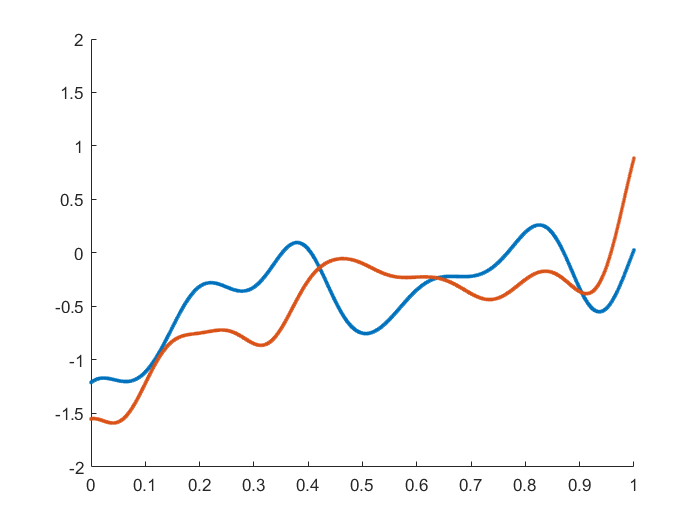

figure(1); hold on;
plot(x,z,'.-')
axis([0 1 -2 2]);